% Initialize the sampling frequency for the acquisition
% Input thhe frequncy in MHz.
sampling_freq = 1.023;

% question 1
CaCode = generatePRNChip(1,sampling_freq)

CaCode =      1     1     1     1    -1    -1    -1    -1     1     1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1     1     1     1     1     1     1    -1    -1    -1    -1     1     1    -1    -1     1     1    -1    -1    -1    -1     1     1    -1    -1    -1    -1     1     1     1     1


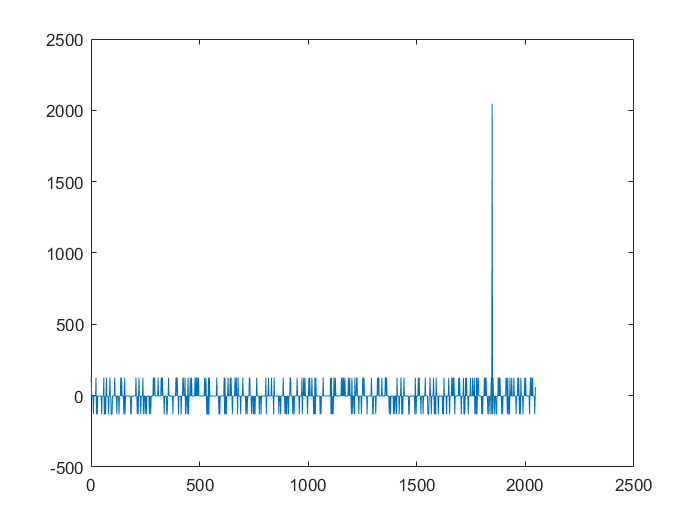


% question 2
autoCorrelation = prnCorrelation(8,0,8,200,sampling_freq);

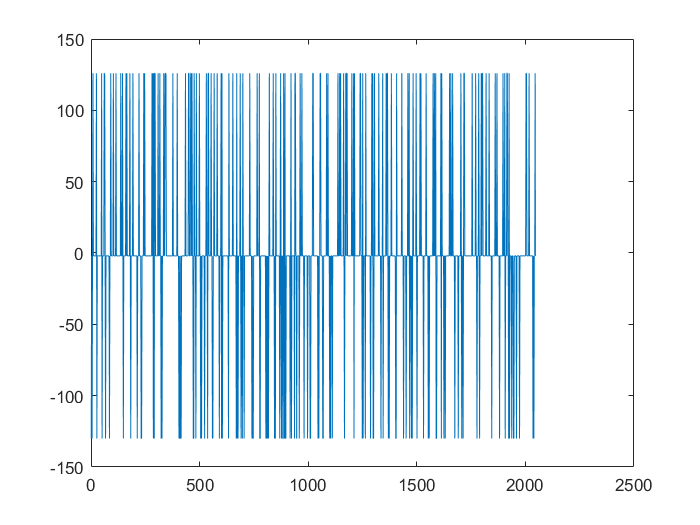


% question 3
crossCorrelation = prnCorrelation(8,0,16,900,sampling_freq);

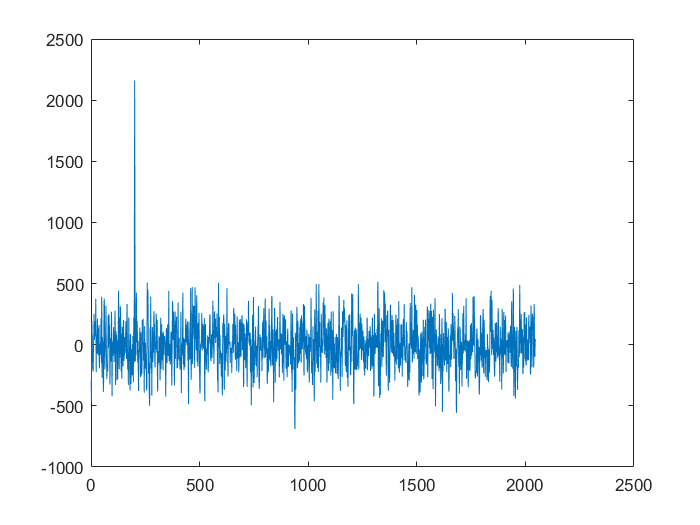


% question 4
awgnValue = autoCorrelationAwgn(8,200,sampling_freq,4);

function CaCode = generatePRNChip(sv_number, sampling_freq)
% Function for generating discretized 1023 chips long PRN code.
% The function takes input for the satellite vehicle number 
% and the sampling frequency in MHz.   
%----------------------------------------------------------------------
%   Inputs:
% 
%        sv_number:   Satellite vehicle number whose PRN is to be 
%                     generated            
%
%            delay:   Delay in the PRN chip
%
%   samplling_freq:   Sampling frequency of the RF frontend(in MHz) 
%
%----------------------------------------------------------------------
%   Outputs:
%
%           CaCode:    Discretized 1023 chips long PRN code.
%----------------------------------------------------------------------


    % initializing the shift registers and storing satellite
    % PRN references for different SV numbers
    f_chip = 1.023e6;
    f_sampling = sampling_freq*1000000;
    x = round(f_sampling/f_chip);
    
    % total number of CA codes recied in 1ms
    n = ceil(f_sampling/1000);
    CaCodePrimary = ones(1,1023);
    shift_register1 = ones(1,10);
    shift_register2 = ones(1,10);
    satellitePrnRef = [2 6;3 7;4 8;5 9;1 9;2 10;1 8;2 9;3 10;2 3;3 4;5 6;...
                       6 7;7 8;8 9;9 10;1 4;2 5;3 6;4 7;5 8;6 9;1 3;4 6;5 ... 
                       7;6 8;7 9;8 10;1 6;2 7;3 8;4 9];
    
    for i=1:1023
        % first, storing the output for P1, which later becomes 
        % the first index of the shift register of P1 
        a1 = mod((shift_register1(3)+shift_register1(10)),2);
        a10 = shift_register1(10);
        
        % shifting the register for P1
        shift_register1 = circshift(shift_register1,1);
        shift_register1(1) = a1;
        
         % taking xor of eliminated index of P1 with satellite
        % specific space vehicle(SV) numbers
        i1 = satellitePrnRef(sv_number,1);
        i2 = satellitePrnRef(sv_number,2);
        CaCodePrimary(i) = mod((a10 + shift_register2(i1) + shift_register2(i2)),2);
        if CaCodePrimary(i) == 0
            CaCodePrimary(i) = -1;
        end
        
        % now, storing the output of P2 and shifting the 
        % shift register for P2
        a2 = mod((shift_register2(2)+shift_register2(3)+shift_register2(6)...
            +shift_register2(8)+shift_register2(9)+shift_register2(10)),2);
        shift_register2 = circshift(shift_register2,1);
        shift_register2(1) = a2;
    end
    
    codeValueIndex = ceil((1:n)/x);
    codeValueIndex(end) = 1023;
    CaCode = CaCodePrimary(codeValueIndex);
end

%---------------------------------------------------------------------------------

function value = prnCorrelation(sv1,delay1,sv2,delay2,sampling_freq)
% Function for calculating the correlation values between two given
% satellites. 
%----------------------------------------------------------------------
%   Inputs:
% 
%         sv1, sv2:   Satellite vehicle numbers of the two incoming 
%                     data streams. Incase of circular autocorrelation,
%                     sv1=sv2.
%  
%   delay1, delay2:   Delay in the PRN chip observed for sv1 and sv2
%                     respectively.
%
%   samplling_freq:   Sampling frequency of the RF frontend(in MHz) 
%
%----------------------------------------------------------------------
%
%   Outputs:
%
%   value:            Correlation value and corresponding plot between 
%                     the two provided satellites' CA code.
%----------------------------------------------------------------------

    % generating the CA codes for the two satellites and inccorporating
    % the delay in PRN chip.
    n = round(sampling_freq*1000);
    CaCode1 = circshift(generatePRNChip(sv1,sampling_freq),delay1);
    CaCode2 = circshift(generatePRNChip(sv2,sampling_freq),delay2);
    value = zeros(1,n);
    
    for i=1:n
        idx = i;
        for j=1:n
            value(1,i) = value(1,i) + CaCode2(j)*CaCode1(idx);
            idx = idx+1;
            if(idx>n)
                idx = 1;
            end
        end
    end
    x = 1:n;
    plot(x,value)
end

%------------------------------------------------------------------------

function value = autoCorrelationAwgn(sv,delay,sampling_freq, stddev)
% Function for calculating the circular autocorrelation values between
% two given satellites with an additional white gaussian noise.
%----------------------------------------------------------------------
%   Inputs:
% 
%               sv:      Satellite vehicle number for the incoming data 
%                        stream
%               
%           stddev:      Standard devaiation of the Gaussian noise to 
%                        be added
%
%            delay:      Delay in the PRN chip observed.
%
%   samplling_freq:      Sampling frequency of the RF frontend(in MHz)
%
%----------------------------------------------------------------------
%
%   Outputs:
%
%   value:            Correlation value and corresponding plot between 
%                     the provided satellites' CA code.
%----------------------------------------------------------------------
    n = ceil(sampling_freq*1000);
    CaCode1 = generatePRNChip(sv,sampling_freq);
    CaCode2 = circshift(generatePRNChip(sv,sampling_freq),delay) + stddev*randn(size(CaCode1));
    value = zeros(1,n);
    
    for i=1:n
        idx = i;
        for j=1:n
            value(1,i) = value(1,i) + CaCode1(j)*CaCode2(idx);
            idx = idx+1;
            if(idx>n)
                idx = 1;
            end
        end
    end
    x = 1:n;
    plot(x,value)
end
